# EMAT30007 Applied Statistics

# Worksheet 1: Random variables, probability distributions and sampling

## Nikolai Bode

This worksheet focusses on the material covered in Lecture 1: Random Variables, PDFs, CDFs and sampling.

## (1) Random Variables (RVs)

In Lecture1 we encountered Random Variables with various distributions: Binomial, Uniform, Exponential, Gamma.

We used these RVs to model data generated by some real world process. For example, we assumed that the outcome of a coin toss is well described by a Binomial (or Bernoulli) RV.

Let's see how to visualise and sample (i.e. generate numbers) from these distributions in Matlab.

**Binomial distribution **$X~\textrm{Binomial}\left(n,p_{\left.\right)} \right)$

The Binomial distribution is a discrete distribution with two parameters: $p\in \left\lbrack 0,1\right\rbrack$ and $n\in N$.

The domain (i.e. possible outcomes) is the set of all integers less or equal to n: $h=0,1,\ldotp \ldotp \ldotp ,n$.

The value $h$ can be interpreted as the number of successes in $n$ independent trials, if the probability of success in each trial is $p$. One example is $h=\textrm{number}\;\textrm{of}\;\textrm{heads}\;\textrm{in}\;n\;\textrm{tosses}\;\textrm{of}\;a\;\left(\textrm{possibly}\;\textrm{unfair}\right)\;\textrm{coin},$where $p$ is the probability of a head. The *Bernoulli distribution* (e.g. the outcome of one coin toss) is a Binomial distribution with $n=1$.

In Matlab, you can get information on a probability distribution and its parameters using `makedist` :

makedist('Binomial')

ans =   BinomialDistribution

  Binomial distribution
    N =   1
    p = 0.5


You can also use `makedist` to create a distribution with specified parameter values:

N = 10;
p = 0.5;
pd = makedist('Binomial', 'N', N, "p", p)

pd =   BinomialDistribution

  Binomial distribution
    N =  10
    p = 0.5


**Theoretical PMF**

The Binomial PMF (probability mass function) is $P_H \left(h;n,p\right)=\left(\overset{n}{h} \right)p^h {\left(1-p\right)}^{n-h}$. In Matlab you can use `pdf(pd, x)` to evaluate the PDF (probability density function) or PMF of a distribution `pd `at the points in $x$.

outcomes = 0:1:10

outcomes =      0     1     2     3     4     5     6     7     8     9    10


binom_pmf = pdf(pd, outcomes)

binom_pmf =     0.0010    0.0098    0.0439    0.1172    0.2051    0.2461    0.2051    0.1172    0.0439    0.0098    0.0010


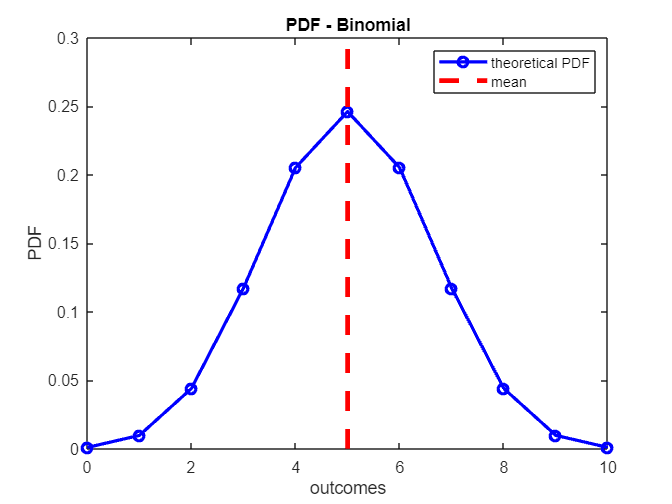

clf; % clear the figure
plot(outcomes, binom_pmf, 'o-b', 'LineWidth', 2)
hold on
binom_mean = mean(pd); % Let's plot the distribution mean
line([binom_mean,binom_mean],[0,0.3], 'LineStyle', '--', 'Linewidth', 3,'Color','red');
legend('theoretical PDF', 'mean', 'Location','northeast')
title('PDF - Binomial') % title for plot
xlabel('outcomes') % x-axis label
ylabel('PDF') % y-axis label

**Generate a random sample**

In Matlab, you can use `random(pd, rows, columns)` to generate a matrix of *rows x columns* random numbers from a specific distribution `pd` defined using `makedist`.

`binornd(N,p,rows,columns)` also generates random numbers from a binomial distribution specified by parameters N and p.

rng('default') % fix the random seed
S = 10 % sample size

S = 10

small_sample = random(pd,1,S) %% use the distributions pd defined above

small_sample =      5     6     2     4     3     7     4     6     3     6


rng('default')
binornd(N,p,1,S)

ans =      5     6     2     4     3     7     4     6     3     6


Here, `rng` sets Matlab's random number generator to a specific seed, so that a given identical sequence of (pseudo)random numbers is generated each time a function is called (ask if you want to find out more).

**Empirical PMF**

Given a list of numbers, the empirical PDF or PMF can be computed using `histogram`

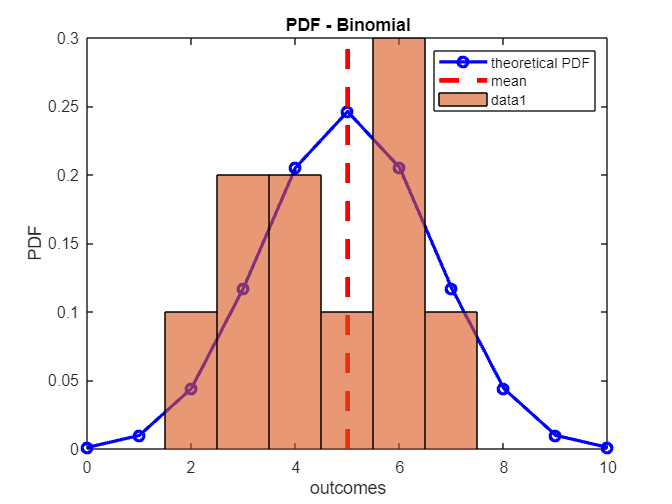

binom_epmf = histogram(small_sample, 'normalization', 'pdf'); % correctly normalised

binom_epmf.Values

ans =     0.1000    0.2000    0.2000    0.1000    0.3000    0.1000


Here the normalisation refers to how the height of the bars in the histogram are computed. Often, the heights just show the frequency of observations in each bin. However, this is not appropriate for comparison to a PMF/PDF. So the bars need to be normalised to ensure the sum of their areas equals to 1.

Let's draw a larger sample with 10000 observations (and specify the bin edges of the histogram). Note that the empirical PMF of the larger sample is very close to the theoretical PMF (circles).

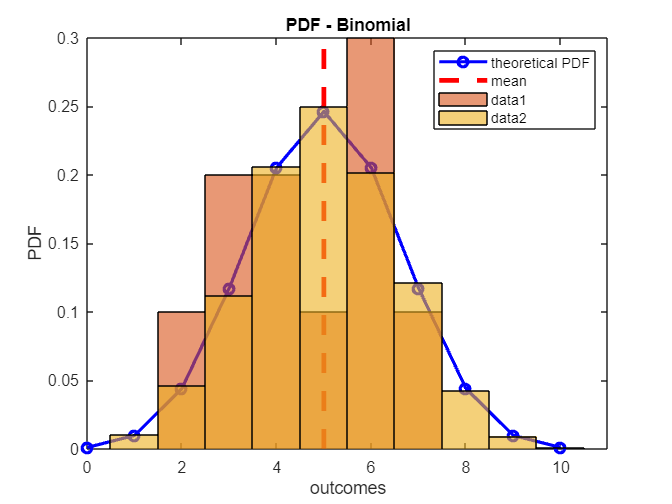

large_sample = random(pd,1,10000);
histogram(large_sample, 'BinEdges', (0.5:1:N+0.5), 'normalization', 'pdf');

**Theoretical CDF**

In Matlab you can use` cdf(pd, x)` to evaluate the Cumulative Distribution Function (CDF) of a distribution `pd` at the points in `x`.

binom_cdf = cdf(pd, outcomes)

binom_cdf =     0.0010    0.0107    0.0547    0.1719    0.3770    0.6230    0.8281    0.9453    0.9893    0.9990    1.0000


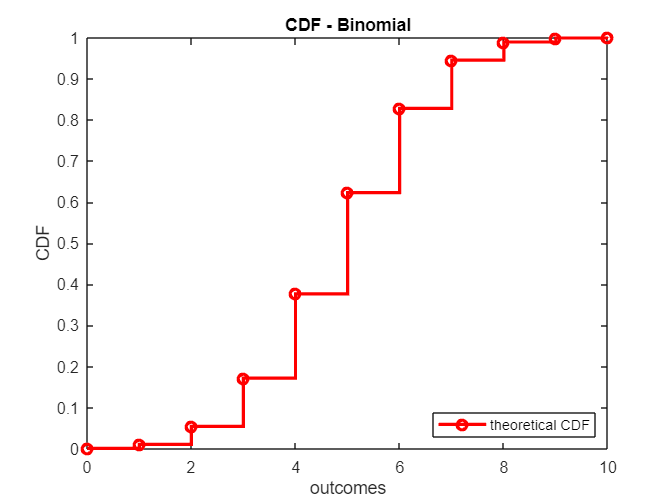

clf % clear the plot
stairs(outcomes, binom_cdf, 'o-r', 'LineWidth', 2)
hold on
legend('theoretical CDF', 'Location','southeast')
title('CDF - Binomial') % title for plot
xlabel('outcomes') % x-axis label
ylabel('CDF') % y-axis label

**Empirical CDF**

Given a list of numbers, data, the empirical CDF can be computed using `ecdf(data):`

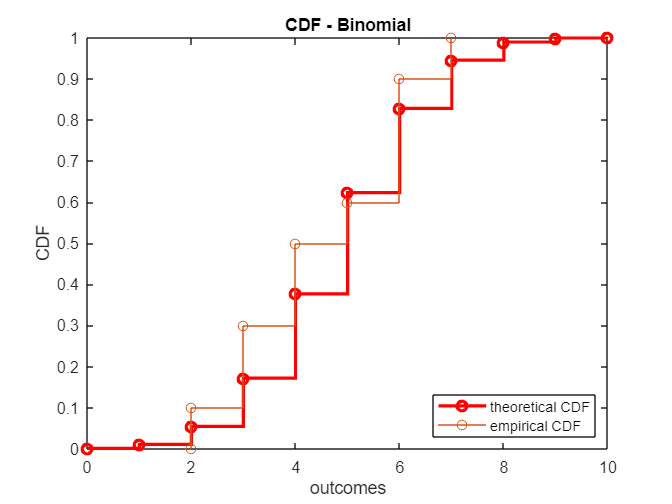

[binom_ecdf, x] = ecdf(small_sample);
stairs(x, binom_ecdf, 'o-')
legend('theoretical CDF','empirical CDF')

The empirical CDF of the larger sample with 10000 observations generated earlier is very close to the theoretical CDF.

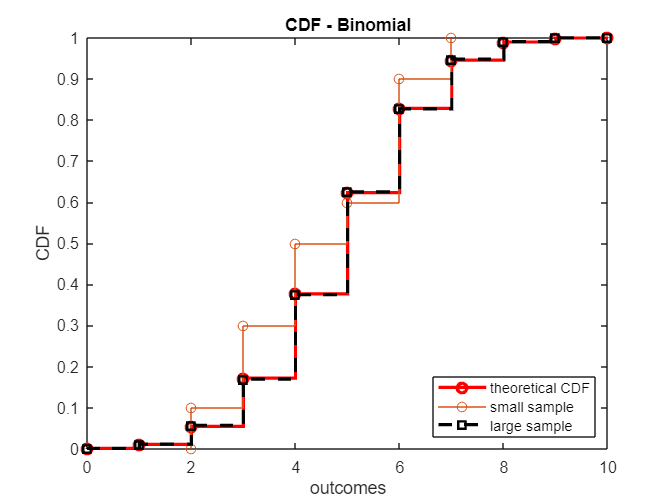

[binom_ecdf, x] = ecdf(large_sample);
stairs(x, binom_ecdf, 's--k', 'LineWidth', 2)
legend('theoretical CDF','small sample', 'large sample')

**Quantile function**

The quantile function is the inverse of the CDF. In Matlab, you can use `icdf(pd, x)` to evaluate the inverse of distribution `pd` at points `x`.

icdf(pd, 0.1)

ans = 3

icdf(pd, 0.2)

ans = 4

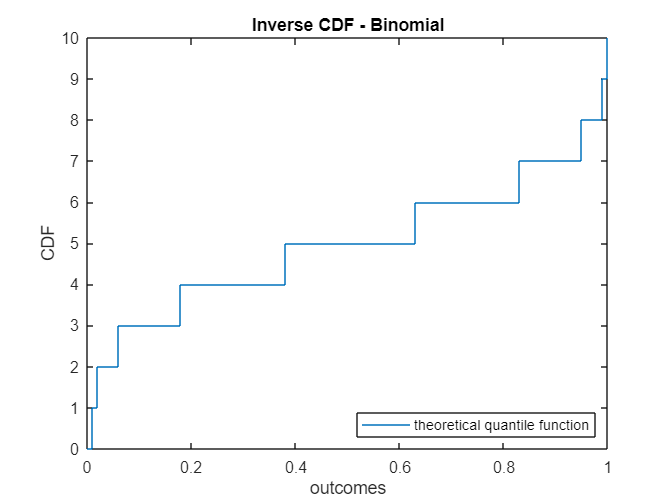

% evaluate at more points within 0 and 1
pp = 0: 0.01: 1;
clf;
stairs(pp, icdf(pd, pp), '-')
hold on
legend('theoretical quantile function', 'Location','southeast')
title('Inverse CDF - Binomial') % title for plot
xlabel('outcomes') % x-axis label
ylabel('CDF') % y-axis label

Use Matlab's function `quantile(data, x)` to compute the empirical quantile of` small_sample` evaluated at points `p` .For the large sample, the empirical quantiles should be close (or identical) to the theoretical ones.

quantile(large_sample, 0.1)

ans = 3

quantile(large_sample, 0.2)

ans = 4

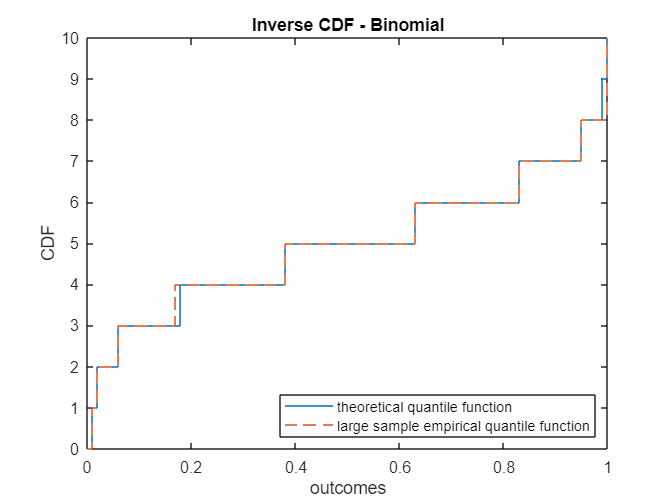

% evaluate at more points within 0 and 1
stairs(pp, quantile(large_sample, pp), '--')
legend('theoretical quantile function', 'large sample empirical quantile function', 'Location','southeast')

**Q-Q plot**

Q-Q plots are used to visually assess if empirical quantiles are close to theoretical ones, or if the quantiles of two distributions are similar. The quantiles of one distribution are plotted against the theoretical ones (or against the quantiles of the other distribution): if the points are aligned along the line $y=x$, then the empirical quantiles is similar to the theoretical ones (or the two distributions are similar). Let's use a Q-Q plot to see if the quantiles of the small and large samples are similar to the quantiles of the theoretical Binomial distribution:

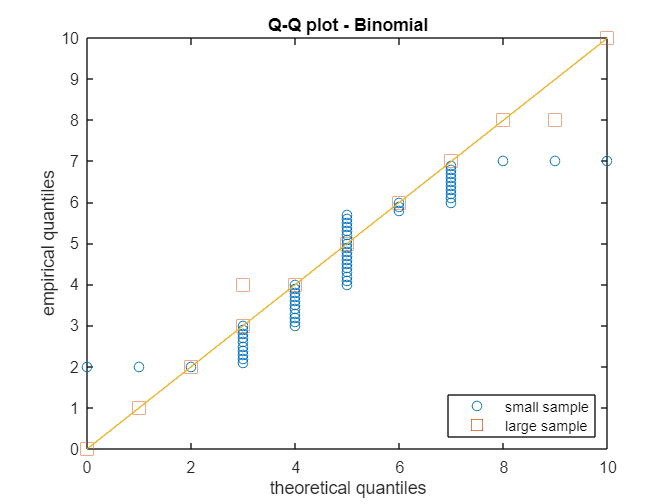

clf;
theor_q = icdf(pd, pp);
empir_q = quantile(small_sample, pp);
empir_q_ls = quantile(large_sample, pp);
plot(theor_q, empir_q, 'o')
hold on
plot(theor_q, empir_q_ls, 's', 'MarkerSize', 10)
hold on
plot(theor_q, theor_q, '-','HandleVisibility','off')
legend('small sample', 'large sample', 'Location','southeast')
title('Q-Q plot - Binomial') % title for plot
xlabel('theoretical quantiles') % x-axis label
ylabel('empirical quantiles') % y-axis label

As expected, the quantiles of the large sample are closer to the theoretical ones than the quantiles of the small sample. The empirical quantiles of discrete distributions can be inaccurate around discontinuity points. The Q-Q plot works better for *continuous distributions*.

## **Common distributions**

Repeat the previous analysis for the following distributions: Uniform, Exponential, Multinomial, Gamma, Normal.

For each distribution, anwser the following questions:

- Is the RV discrete or continuous?

- What is the domain of the RV's PDF or PMF ?

- Describe the parameters of the distribution: how many are they? What values can they take?

- Give one example of real world phenomenon or data that could be modelled using the distribution.

and complete the following tasks:

- Plot the (theoretical) PDF (for contiuous RVs) or PMF (for discrete RVs) and the mean

- Draw a sample of $S=1000$ random outcomes.

- Plot the empirical PDF or PMF of these samples on the same plot created in task 1.

- Plot the (theoretical) CDF

- Plot the empirical CDF of the samples generated in task 2 on the same plot created in task 4.

- Use a Q-Q plot to show the similarity between empirical and theoretical quantiles.

**The answers to this section can be found in the distributions folder.**

## 2. Estimate the probability of events

The probability to observe an outcome within a contiguous range of values, for example $\left\lbrack x_0 ,x_1 \right\rbrack$, can be computed using the CDF function $F_X \left(x\right)$ as $\Pr \left(x_0 \le X<x_1 \right)=F_X \left(x_1 \right)-F_X \left(x_0 \right)$

Compute the probabilities of these events

-  That $x\in \left\lbrack 5,6\right\rbrack$, for RV $X$ with Exponential distribution $P_X \left(x\right)=e^{-x/\mu } /\mu$ and parameter $\mu =4$.

pd = makedist('Exponential', 'mu', 4);
cdf(pd, 6) - cdf(pd, 5)

ans = 0.0634

-  That the outcome of a Standard Normal RV with $\mu =0$ and $\sigma =1$is within $-\sigma$ and $\sigma$ (i.e. $x\in \left\lbrack -\sigma ,\sigma \right\rbrack$). Does your result depend on σ? **0.6827. It does not depend on **$\sigma$

pd = makedist('Normal', 'mu', 0, 'sigma', 1);
cdf(pd, 1) - cdf(pd, -1)

ans = 0.6827

- You arrive at a bus stop and you read that there is a bus every hour. If you arrived at a random time, what is the probability that you'll wait between 5 and 20 minutes before the next bus arrives? And between 30 and 45 minutes? And between 55 and 70 minutes?

% Uniform distribution between 1 and 60.
pd = makedist('Uniform', 'lower', 0, 'upper', 60);

% Between 5 and 20 minutes
cdf(pd, 20) - cdf(pd, 5)

ans = 0.2500

% Between 30 and 45
cdf(pd, 45) - cdf(pd, 30)

ans = 0.2500

% Between 55 and 70
cdf(pd, 70) - cdf(pd, 55)

ans = 0.0833

## 3. Compute the empirical CDF from data

The CDF is defined in Eq.(1) of Lecture 1 a


$$F_X \left(x\right)=\textrm{Prob}\left(X\le x\right)$$


The empirical CDF can be computed following the steps described in Lecture 1:

- Sort data in ascending order, x.

- Create an array,$y$, of increasing integers from 1 to the length of $x$.

- Divide each element of $y$ by the length of $x$, so that the max of $y$ is 1.

- If there are $\left(x_i ,y_i \right)$ pairs with identical x-value, keep only the pair with the largest y-value $y=F_x \left(x\right)$.

Use the above steps to compute the empirical CDF of the following dataset `data` and compare your result with the output of Matlab's `ecdf` function.

data = [0.9838 1.1704 6.8989 1.7893 1.5168 0.1136 6.3209 1.6271 3.8187 3.5633];

% sort data in ascending order, x
x = sort(data)

x =     0.1136    0.9838    1.1704    1.5168    1.6271    1.7893    3.5633    3.8187    6.3209    6.8989


% create array y of increasing integers of size length(x)
y = (1: 1: length(x))

y =      1     2     3     4     5     6     7     8     9    10


% divide y by length(x)
y = y ./ length(x)

y =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


% Matlab's CDF
[y_ecdf, x_ecdf] = ecdf(data)

y_ecdf =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


x_ecdf =     0.1136
    0.1136
    0.9838
    1.1704
    1.5168
    1.6271
    1.7893
    3.5633
    3.8187
    6.3209


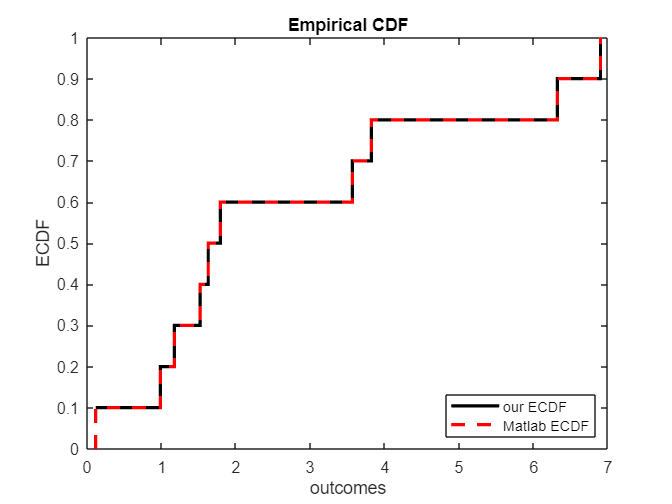

clf;
stairs(x, y, '-k', 'LineWidth', 2);
hold on
stairs(x_ecdf, y_ecdf, '--r', 'LineWidth', 2)
legend('our ECDF', 'Matlab ECDF', 'Location', 'southeast')
title('Empirical CDF') % title for plot
xlabel('outcomes') % x-axis label
ylabel('ECDF') % y-axis label

It is assumed that the ECDF values of all outcomes smaller than `min(data)` are zero and the ECDF values of all outcomes larger than `max(data)` are one.

## 4. Compute the empirical PDF from data

The empirical PDF of a data sample can be computed following the steps described in Lecture 1:

- Divide the range of data, `[min(data) max(data)]`, into bins, with bin edges $b$.

- Compute the mid-point of each bin, $x_1 =\left(b_{i+1} +b_i \right)/2$.

- Count the number of data elements that fall in each bin, $c_i =\left|\left\lbrace d_j :b_i \le d_j <b_{i+1} \right\rbrace \right|$.

- Normalise. Rescale each element of $c$: $y_i =c_i /\left(\left|d\right|\left(b_{i+1} -b_i \right)\right)$, so that the PDF integral is 1. $y=P_x \left(x\right)$.

Use the above steps to compute the empirical PDF of the following dataset `data` uysing bin edges `bin_edges` and compare your result with the output of Matlab's `histogram` function.

data = [0.9838 1.1704 6.8989 1.7893 1.5168 0.1136 6.3209 1.6271 3.8187 3.5633];
bin_edges = 0: 3: 12;
% compute bins' mid points
x = (bin_edges(1: end-1) + bin_edges(2: end)) / 2

x =     1.5000    4.5000    7.5000   10.5000


% count the number of data points that fall in each bin
[c, edges] = histcounts(data, bin_edges)

c =      6     2     2     0


edges =      0     3     6     9    12


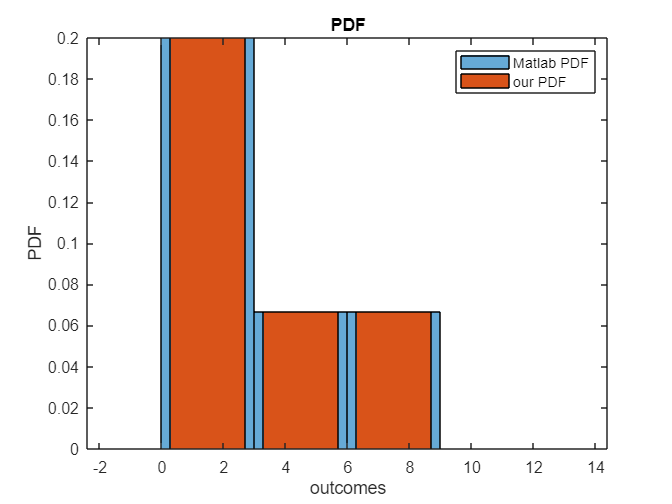

% normalise
y = zeros(1, length(c));
for i = 1:length(c)
y(i) = c(i) / (length(data) * (bin_edges(i+1) - bin_edges(i)));
end
clf;
histogram(data, 'BinEdges', bin_edges, 'normalization', 'pdf');
hold on
bar(x, y)
legend('Matlab PDF', 'our PDF', 'Location', 'northeast')
title('PDF') % title for plot
xlabel('outcomes') % x-axis label
ylabel('PDF') % y-axis label

Change the size of the bin edges and check that the PDF is correctly normalised. Is it normalised even if bins have varying sizes, like `bin_edges = [0 0.75 1.5 3 5 8 12]`?

## 5. Inverse Probability Integral Transform (IPIT) sampling

To sample from RV $X$ with inverse CDF (i.e. the quantile function) $F_X^{-1}$:

- Generate a number $u$ from the uniform distribution $U\left(0,1\right)$.

- Compute ${x=F}_X^{-1} \left(u\right)$.

***Use the IPIT to draw 1000 independent observations from a Normal distribution with ***$\mu =5$*** and ***$\sigma =3$

Plot the empirical PDF (histogram) of the generated data and the theoretical PDF on the same figure.

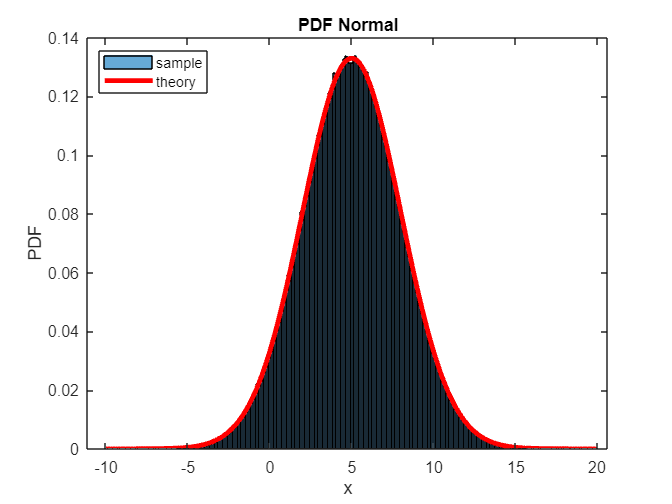

% generate uniform random numbers
unif = makedist('Uniform', 'lower', 0, 'upper', 1);
u_samples = random(unif, 1000);
% compute the inverse CDF of the desired distribution
pd = makedist('Normal', 'mu', 5, 'sigma', 3);
x_samples = icdf(pd, u_samples);
% PDFs
clf;
histogram(x_samples, 'normalization', 'pdf');
hold on;
x = -10: 0.1: 20;
th_pdf_x = pdf(pd, x);
plot(x, th_pdf_x, '-r', 'LineWidth', 3)
legend('sample', 'theory', 'Location', 'northwest')
title('PDF Normal') % title for plot
xlabel('x') % x-axis label
ylabel('PDF') % y-axis label

***Use the IPIT to draw samples from a multinomial distribution representing the sum of two fair dice.***

For discrete distributions like this one, you can use the following code to get the quantile value, $F_X^{-1} \left(u\right)$, of number $u$:

`outcomes(min(find(th_cdf > u)))`, where `th_cdf `is the RV's CDF.

Plot the empirical PDF(histogram) of the generated data and the theoretical PDF on the same figure.

**For discrete distributions, the quantile != icdf**

**For continuous distributions, the quantile == icdf**

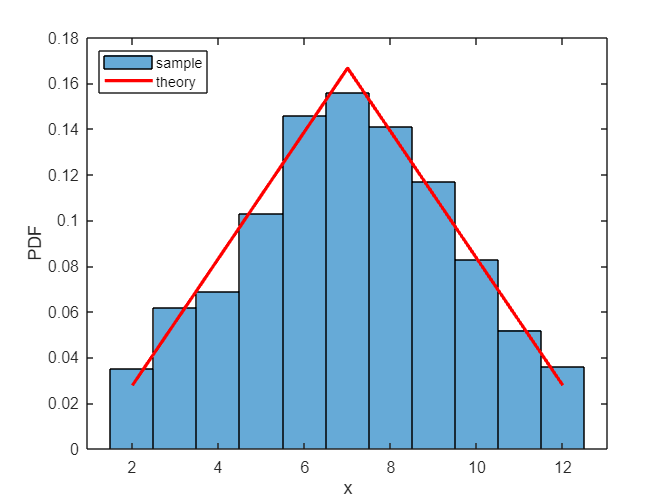

outcomes = (2:1:12);
th_pdf = [1, 2, 3, 4, 5, 6, 5, 4, 3, 2, 1]/36;
th_cdf = cumsum(th_pdf);

% Generate samples between 0 and 1
S = 1000;
unif = makedist('Uniform', 'lower', 0, 'upper', 1);
u_samples = random(unif, S);

x_samples = zeros(1, S);
for i = 1:S
    u = u_samples(i);
    x_samples(i) = outcomes(min(find(th_cdf > u)));
end

% Plot data
clf
histogram(x_samples, 'normalization', 'pdf');
hold on
% Theoretical PDF
plot(outcomes, th_pdf, '-r', 'LineWidth', 2)
legend('sample', 'theory', 'Location', 'northwest')
xlabel('x') % x-axis label
ylabel('PDF') % y-axis label